addpath('C:\Users\Siddarth\Documents\MATLAB')
import casadi.*

## Missile Longitudinal Dynamics

A = [-1.064 1.000; 290.26 0.00];
B = [-0.25; -331.40];
C = [-123.34 0.00; 0.00 1.00];
D = [0;0];
plant = ss(A,B,C,D);

% Check system properties
if rank(ctrb(A,B)) == size(A,1), disp("System is controllable"), end

System is controllable


if rank(obsv(A,C)) == size(A,1), disp("System is observable"), end

System is observable


## Discretization

Ts = 0.1;
sysd = c2d(plant,Ts);
Ad = sysd.A; Bd = sysd.B; Cd = sysd.C; Dd = sysd.D;

nx = size(Ad,1); nu = size(Bd,2); ny = size(Cd,1);
Qy = diag([2, 0.5]); R = 1;

## CasADi symbolic model

x = MX.sym('x',nx); u = MX.sym('u',nu);
x_next = Ad*x + Bd*u;
f = Function('f',{x,u},{x_next});

## MPC setup

N = 10;
x0_val = [0; 0];
U = MX.sym('U',nu,N);
X = MX.sym('X',nx,N+1);
x0 = MX.sym('x0',nx);

## Reference tracking

Az_step = linspace(0, 15, N);  % target normal acceleration (g)
q_ref = zeros(1, N);           % target pitch rate
y_ref = [Az_step; q_ref];

## 3D estimation parameters

Vel = 1021.08;  % m/s constant forward velocity
n_steps = 50;
x_sim = zeros(nx, n_steps+1); u_sim = zeros(nu, n_steps);
x_sim(:,1) = x0_val;
pitch_angle = zeros(1,n_steps+1);
x_pos = zeros(1,n_steps+1);
z_pos = zeros(1,n_steps+1);

x_pos(1)=1590;
z_pos(1) = 10000;  % initial height

## MPC loop

for t = 1:n_steps
    cost = 0; g = {};
    g{end+1} = X(:,1) - x0;

    % Predict pitch angle symbolically
    pitch_pred = MX.zeros(1,N+1);
    pitch_pred(1) = pitch_angle(t);     

    % Predict 3D trajectory symbolically
    x_pos_pred = MX.zeros(1,N+1);
    z_pos_pred = MX.zeros(1,N+1);
    x_pos_pred(1) = x_pos(t);
    z_pos_pred(1) = z_pos(t);

    for k = 1:N
        pitch_pred(k+1) = pitch_pred(k) + X(2,k)*Ts;
        x_k = X(:,k); u_k = U(:,k);
        x_next = f(x_k, u_k);
        g{end+1} = X(:,k+1) - x_next;

        % Tracking cost
        y_k = C * x_k;
        y_ref_k = y_ref(:,k);
        cost = cost+(y_k - y_ref_k)' * Qy * (y_k - y_ref_k) + u_k'*R*u_k;

        % Position integration
        x_pos_pred(k+1) = x_pos_pred(k) + Vel*cos(pitch_pred(k+1))*Ts;
        z_pos_pred(k+1) = z_pos_pred(k) + Vel*sin(pitch_pred(k+1))*Ts;
    end

    % Terminal soft constraint to target position
    target = [10500; 300];
    final_pos = [x_pos_pred(end); z_pos_pred(end)];
    Qterm = 0.01 * eye(2);
    cost = cost + (final_pos - target)' * Qterm * (final_pos - target);

    % Solve
    opt_vars = [reshape(X, nx*(N+1), 1); reshape(U, nu*N, 1)];
    nlp = struct('x',opt_vars,'f',cost,'g',vertcat(g{:}),'p',x0);
    solver = nlpsol('solver','ipopt',nlp,struct('ipopt',struct('print_level',0)));

    % Initial guesses
    U0 = zeros(nu,N); X0 = repmat(x_sim(:,t),1,N+1); w0 = [X0(:);U0(:)];
    sol = solver('x0',w0,'p',x_sim(:,t),'lbg',0,'ubg',0);
    w_opt = full(sol.x);
    U_opt = reshape(w_opt(nx*(N+1)+1:end),nu,N);

    % Apply control and update states
    u0 = U_opt(:,1); u_sim(:,t) = u0;
    x_sim(:,t+1) = Ad * x_sim(:,t) + Bd * u0;

    % Update pitch and trajectory
    pitch_angle(t+1) = pitch_angle(t) + x_sim(2,t)*Ts;
    x_pos(t+1) = x_pos(t) + Vel*cos(pitch_angle(t+1))*Ts;
    z_pos(t+1) = z_pos(t) + Vel*sin(pitch_angle(t+1))*Ts;
end

      solver  :   t_proc      (avg)   t_wall      (avg)    n_eval
       nlp_f  |        0 (       0)  90.00us ( 18.00us)         5
       nlp_g  |        0 (       0)  51.00us ( 10.20us)         5
  nlp_grad_f  |   2.00ms (333.33us) 202.00us ( 33.67us)         6
  nlp_hess_l  |   1.00ms (250.00us) 883.00us (220.75us)         4
   nlp_jac_g  |        0 (       0) 164.00us ( 27.33us)         6
       total  |  13.00ms ( 13.00ms)  12.64ms ( 12.64ms)         1
      solver  :   t_proc      (avg)   t_wall      (avg)    n_eval
       nlp_f  |   1.00ms ( 38.46us) 455.00us ( 17.50us)        26
       nlp_g  |        0 (       0) 271.00us ( 10.42us)        26
  nlp_grad_f  |        0 (       0) 613.00us ( 27.86us)        22
  nlp_hess_l  |   3.00ms (150.00us)   4.58ms (229.00us)        20
   nlp_jac_g  |   1.00ms ( 45.45us) 585.00us ( 26.59us)        22
       total  |  35.00ms ( 35.00ms)  34.62ms ( 34.62ms)         1
      solver  :   t_proc      (avg)   t_wall      (avg)    n_eval
       nlp

## Plot results

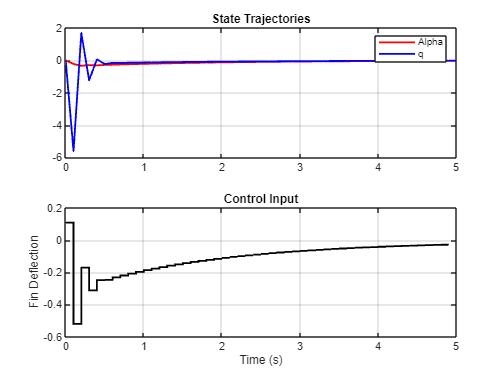

time = 0:Ts:n_steps*Ts;

figure;
subplot(2,1,1);
plot(time, x_sim(1,:), 'r', 'LineWidth', 1.5); hold on;
plot(time, x_sim(2,:), 'b', 'LineWidth', 1.5);
legend('Alpha', 'q'); title('State Trajectories'); grid on;

subplot(2,1,2);
stairs(time(1:end-1), u_sim, 'k', 'LineWidth', 1.5);
title('Control Input'); xlabel('Time (s)'); ylabel('Fin Deflection'); grid on;

## 3D Trajectory Visualization

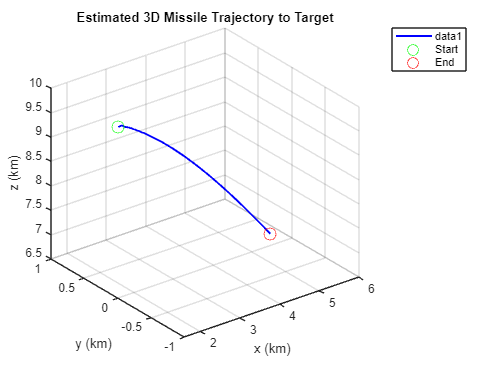

y_pos = zeros(size(x_pos));  % 2D path
figure;
plot3(x_pos/1000, y_pos/1000, z_pos/1000, 'b', 'LineWidth', 1.5); hold on;
plot3(x_pos(1)/1000, 0, z_pos(1)/1000, 'go', 'MarkerSize', 10, 'DisplayName','Start');
plot3(x_pos(end)/1000, 0, z_pos(end)/1000, 'ro', 'MarkerSize', 10, 'DisplayName','End');
xlabel('x (km)'); ylabel('y (km)'); zlabel('z (km)');
title('Estimated 3D Missile Trajectory to Target'); legend; grid on;

## 3D Missile Animation

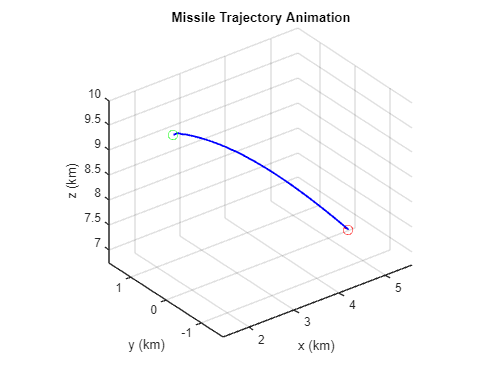

% Missile body dimensions (in km)
missile_length = 0.1; % 100 meters
missile_radius = 0.02; % 20 meters

% Create cone-shaped missile geometry
[cone_x, cone_y, cone_z] = cylinder([0 missile_radius], 20);
cone_z = missile_length * cone_z;

% Create figure
figure;
hold on;
axis equal;
grid on;
xlabel('x (km)'); ylabel('y (km)'); zlabel('z (km)');
title('Missile Trajectory Animation');
view(3);

% Plot trail
h = plot3(x_pos(1)/1000, y_pos(1)/1000, z_pos(1)/1000, 'b', 'LineWidth', 1.5);

% Plot start and end
plot3(x_pos(1)/1000, y_pos(1)/1000, z_pos(1)/1000, 'go', 'MarkerSize', 8, 'DisplayName','Start');
plot3(x_pos(end)/1000, y_pos(end)/1000, z_pos(end)/1000, 'ro', 'MarkerSize', 8, 'DisplayName','End');

% Set up missile surface (initially hidden)
missile_surf = surf(nan(size(cone_x)), nan(size(cone_y)), nan(size(cone_z)), ...
    'FaceColor', 'r', 'EdgeColor', 'none');

% Loop through trajectory
for k = 2:length(x_pos)
    % Missile center position (in km)
    center = [x_pos(k), y_pos(k), z_pos(k)] / 1000;

    % Get current pitch angle
    theta = pitch_angle(k);  % already in radians

    % Rotation matrix (around y-axis)
    R = [cos(theta) 0 sin(theta);
         0          1        0;
        -sin(theta) 0 cos(theta)];

    % Rotate and translate cone
    rotated = R * [cone_x(:)'; cone_y(:)'; cone_z(:)'];
    Xr = reshape(rotated(1,:) + center(1), size(cone_x));
    Yr = reshape(rotated(2,:) + center(2), size(cone_y));
    Zr = reshape(rotated(3,:) + center(3), size(cone_z));

    % Update missile surface
    set(missile_surf, 'XData', Xr, 'YData', Yr, 'ZData', Zr);

    % Update trail
    set(h, 'XData', x_pos(1:k)/1000, ...
           'YData', y_pos(1:k)/1000, ...
           'ZData', z_pos(1:k)/1000);

    drawnow;
    pause(0.5);
end